# Cinemática

trf 1bclc;
clear all;

## Cinemática Directa

### Denavit Hatenberg

Un robot en articulado o en serie con $n$ articulaciones tendrá $n+1$ eslabones o cuerpos. La numeración de los enlaces comienza desde $\left(0\right)$ para el enlace base puesto a tierra inmóvil y aumenta secuencialmente hasta $\left(n\right)$ para el enlace del efector final. La numeración de las articulaciones comienza desde 1, para la articulación que conecta el primer eslabón móvil con el eslabón base, y aumenta secuencialmente hasta $n$. Por lo tanto, el eslabón $\left(i\right)$ está conectado a su eslabón inferior $\left(i-1\right)$ en su extremo proximal por la articulación $i$ y está conectado a su eslabón superior $\left(i+1\right)$ en su extremo distal por la articulación $i+1$. 

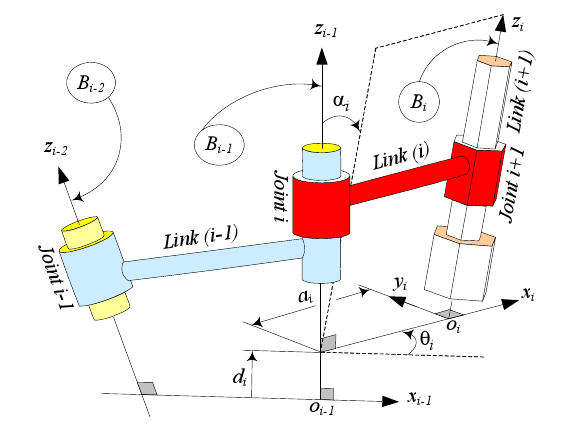

1. El eje $z_{i\;}$está alineado con el eje de articulación $i+1$.

2. El eje $x_{i\;}$ se define a lo largo de la normal común entre los ejes $z_{i-1}$ y $z_{i\;}$, apuntando desde el eje $z_{i-1}$ al eje $z_i$.  

- Cuando los dos ejes $z$ son paralelos, hay un número infinito de normales comunes. En ese caso, elegimos la normal común que escolineal con la normal común de las juntas anteriores.

- Cuando los dos ejes $z$ se intersecan, no existe una normal común entre ellos. En ese caso, asignamos el eje $x_{i\;}$ perpendicular al plano formado por los dos ejes $z$ en la dirección de $z_{i-1} \times z_i$.

- En caso de que los dos ejes $z$ sean colineales, la única disposición no trivial de las juntas es $P\parallel R$ or $R\parallel P$. Por lo tanto, asignamos el eje $x_i$ de manera que tengamos la variable conjunta igual a $\theta_{i\;}$ en la posición de reposo del robot. 

3. El eje $y_{i\;}$ está determinado por la regla de la mano derecha, $y_i =z_{i\;} \times x_{i\;}$. 

El método DH tiene 4 parámetros

1. Ángulo de giro del eslabón $\alpha_{i\;}$ es la rotación requerida del eje $z_{i-1}$ sobre el $x_i$ eje para volverse paralelo al eje $z_{i\;}$.

2. La longitud del eslabón $a_i$ es la distancia entre los ejes $z_{i-1}$ y $z_{i\;}$ a lo largo del eje  es la longitud cinemática del enlace (i).

3. El ángulo de articulación $\theta_{i\;}$ es la rotación requerida del eje $x_{i-1}$ sobre el eje $z_{i-1}$ para volverse paralelo al eje $x_i$.

4. La distancia de articulación $d_{i\;}$ es la distancia entre los ejes $x_{i-1}$ y $x_{i\;}$a lo largo del eje $z_{i-1}$. La distancia de articulación también se denomina desplazamiento de enlace.

De acuerdo con los pasos anteriores la transformación homogenea ${}^{i-1}{\mathit{\mathbf{T}}}_i=\mathit{\mathbf{D}}\left({}^{i-1}{\mathbf{k}},d_{i\;} \right)\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{k}}{,\;\theta }_{i\;} \right)\mathit{\mathbf{D}}\left({}^{i-1}{\mathbf{i}},a_{i\;} \right)\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{i}},\alpha_{i\;} \right)$

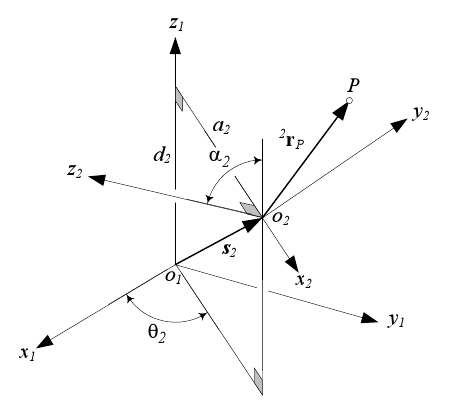


$$\begin{array}{l}
{}^{i-1}{\mathit{\mathbf{T}}}_i=\mathit{\mathbf{D}}\left({}^{i-1}{\mathbf{k}},d_{i\;} \right)\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{k}}{,\;\theta }_{i\;} \right)\mathit{\mathbf{D}}\left({}^{i-1}{\mathbf{i}},a_{i\;} \right)\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{i}},\alpha_{i\;} \right)\\
{}^{i-1}{\mathit{\mathbf{T}}}_i=\left\lbrack \begin{array}{cc}
\mathit{\mathbf{I}} & d_{i\;} {}^{i-1}{\mathbf{k}}\\
\vec{0}  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{k}},\theta_{i\;} \right) & 0\;{}^{i-1}{\mathbf{k}}\\
\vec{0}  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
\mathit{\mathbf{I}} & a_{i\;} {}^{i-1}{\mathbf{i}}\\
\vec{0}  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{i}},\alpha_{i\;} \right) & 0\;{}^{i-1}{\mathbf{i}}\\
\vec{0}  & 1
\end{array}\right\rbrack \\
{}^{i-1}{\mathit{\mathbf{T}}}_i=\left\lbrack \begin{array}{cc}
\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{k}},\theta_{i\;} \right) & d_{i\;} \;{\mathbf{k}}_{i-1} \\
\vec{0}  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{i}},\alpha_{i\;} \right) & a_i \;{}^{i-1}{\mathbf{i}}\\
\vec{0}  & 1
\end{array}\right\rbrack \\
{}^{i-1}{\mathit{\mathbf{T}}}_i=\left\lbrack \begin{array}{cc}
\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{k}},\theta_{i\;} \right)\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{i}},\alpha_{i\;} \right) & d_{i\;} \;{\mathbf{k}}_{i-1} +\mathit{\mathbf{R}}\left({}^{i-1}{\mathbf{k}},\theta_{i\;} \right)a_i \;{}^{i-1}{\mathbf{i}}\\
\vec{0}  & 1
\end{array}\right\rbrack 
\end{array}$$


### Construcción de robot

clc;
clear all;

Para el cuerpo 1 y su junta con la base.

%Declarar eslabon1
body1 = rigidBody('body1') 

body1 =   rigidBody with properties:

            Name: 'body1'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


%Declarar una junta/articulacion1 entre la base y el eslabon1 
jnt1 = rigidBodyJoint('jnt1','revolute')

jnt1 =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'jnt1'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 0
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


jnt1.HomePosition = pi/3               %Posicion inicial de la junta

jnt1 =   rigidBodyJoint with properties:

                      Type: 'revolute'
                      Name: 'jnt1'
                 JointAxis: [0 0 1]
            PositionLimits: [-3.1416 3.1416]
              HomePosition: 1.0472
    JointToParentTransform: [4×4 double]
     ChildToJointTransform: [4×4 double]


tform = trvec2tform([0.25, 0.25, 0])    %Transformación homogenea de un vector de traslacion 3D

tform =     1.0000         0         0    0.2500
         0    1.0000         0    0.2500
         0         0    1.0000         0
         0         0         0    1.0000


setFixedTransform(jnt1,tform)          %Se adjunta la transformacion homogenea a la junta
body1.Joint = jnt1                     %Se agrega al eslabon1 la junta 1

body1 =   rigidBody with properties:

            Name: 'body1'
           Joint: [1×1 rigidBodyJoint]
            Mass: 1
    CenterOfMass: [0 0 0]
         Inertia: [1 1 1 0 0 0]
        Children: {1×0 cell}
         Visuals: {}
      Collisions: {}


Construccion de la cadena cinemática

robot = rigidBodyTree           %la cadena cinemática se contiene en una estructura rigidBodyTree

robot =   rigidBodyTree with properties:

     NumBodies: 0
        Bodies: {1×0 cell}
          Base: [1×1 rigidBody]
     BodyNames: {1×0 cell}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'struct'


addBody(robot,body1,'base')     %Agrega eslabon1 a la base, mediante junta1 

Desplegar resultados actuales

showdetails(robot)              %Despliega los actuales elementos dentro de la cadena cinematica

--------------------
Robot: (1 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   
--------------------


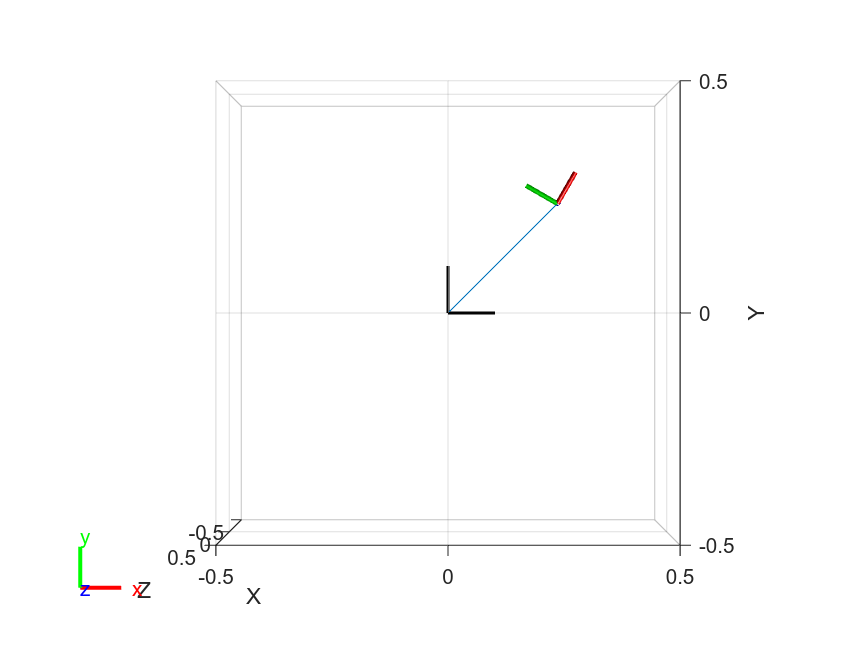

figure(1);          %Muestra sistemas coordenados
show(robot);        %Muestra el robot dentro de un espacio 3D
view(2)             %Restringimos la vista a 2D

Agregar un segundo cuerpo

body2 = rigidBody('body2');                     %Declaración de eslabon2
jnt2 = rigidBodyJoint('jnt2','revolute');       %Junta entre eslabon1 y eslabon2, junta2
jnt2.HomePosition = pi/2;                       %Posición original
tform2 = trvec2tform([1, 0, 0]);                %Vector de traslación definido en transformación homogenea
setFixedTransform(jnt2,tform2);                 %Se adjunta la transformación a la junta2
body2.Joint = jnt2;                             %Se agrega la junta al cuerpo
addBody(robot,body2,'body1');                   %Se agrega el cuerpo2 al cuerpo1 mediante la junta2

Desplegar resultados

showdetails(robot)      %Despliega los actuales elementos dentro de la cadena cinematica

--------------------
Robot: (2 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   
--------------------


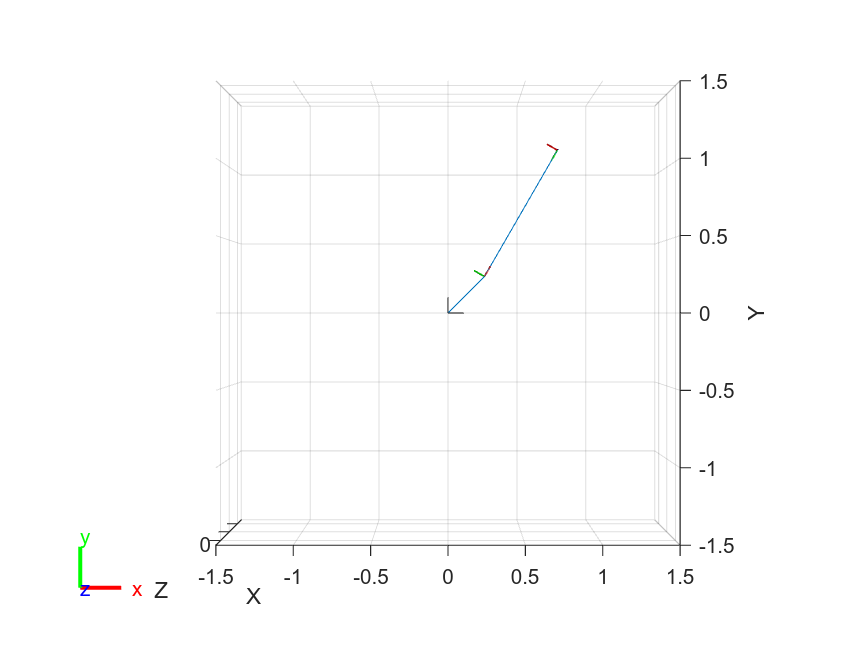

figure(2);              %Muestra sistemas coordenados
show(robot);            %Muestra el robot dentro de un espacio 3D
view(2) 

### Construcción mediante parametros DH

clc;
clear all;
dhparams = [0.25*sqrt(2), 0, 0, pi/6;
            1,            0, 0, pi/2]

dhparams =     0.3536         0         0    0.5236
    1.0000         0         0    1.5708


robot = rigidBodyTree;
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
setFixedTransform(jnt1,dhparams(1,:),'dh');
body1.Joint = jnt1;
addBody(robot,body1,'base')
jnt1.ChildToJointTransform

ans =     1.0000         0         0    0.3536
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
setFixedTransform(jnt2,dhparams(2,:),'dh');
body2.Joint = jnt2;
addBody(robot,body2,'body1')
jnt2.ChildToJointTransform

ans =      1     0     0     1
     0     1     0     0
     0     0     1     0
     0     0     0     1


showdetails(robot)      %Despliega los actuales elementos dentro de la cadena cinematica

--------------------
Robot: (2 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   
--------------------


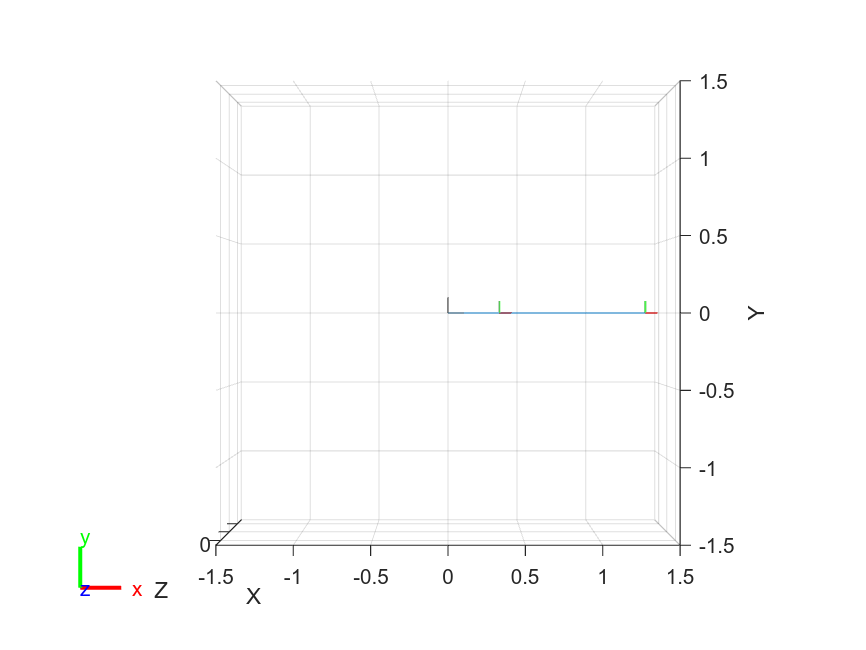

figure(2);              %Muestra sistemas coordenados
show(robot);            %Muestra el robot dentro de un espacio 3D
view(2) 

Construcción de un Robot Puma

Determinar los paramatros DH sin contar con el efector final

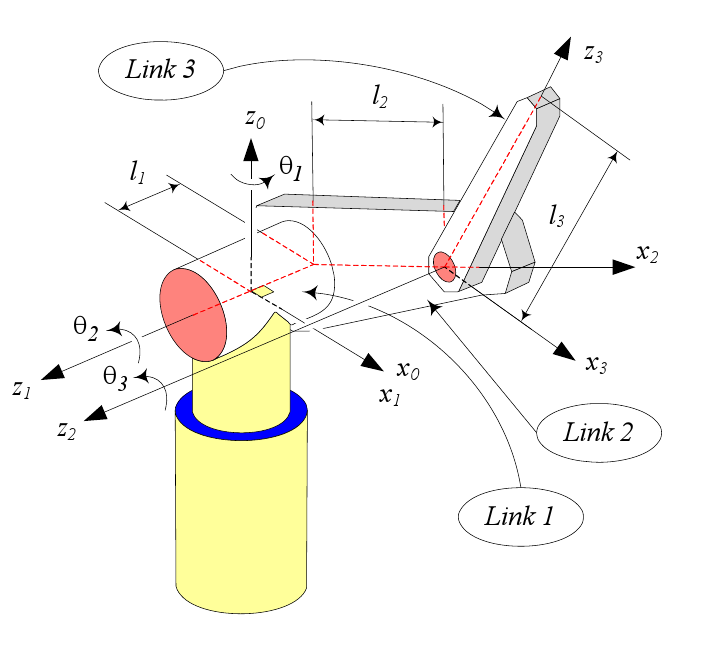


$$\left\lbrack \begin{array}{ccccc}
i & a_{i\;}  & \alpha_i  & d_i  & \theta_i \\
1 & 0 & \frac{\pi }{2} & 0 & \theta_1 \\
2 & l_2  & 0 & l_1  & \theta_2 \\
3 & 0 & -\frac{\pi }{2} & 0 & \theta_3 
\end{array}\right\rbrack$$
